x = load('HeadEEGSADopensignals_ecg2_201607182369_2020-02-01_23-42-16.txt')

x =      0     0     0     0     0   404
     1     0     0     0     0   392
     2     0     0     0     0   372
     3     0     0     0     0   353
     4     0     0     0     0   342
     5     0     0     0     0   348
     6     0     0     0     0   347
     7     0     0     0     0   339
     8     0     0     0     0   334
     9     0     0     0     0   333



Fs=1000  %%sampling frequency

Fs = 1000

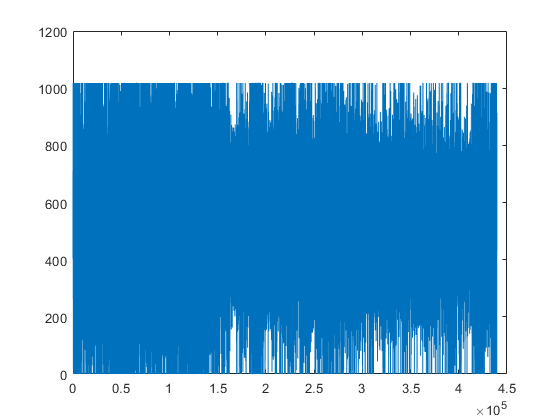


t=1/Fs;
S=x(:,6);
waveletFunction = 'db8';
[C,L] = wavedec(S,8,waveletFunction);

plot(S);

## Calculating the coefficients vectors

cD1 = detcoef(C,L,1); %NOISY
cD2 = detcoef(C,L,2); %NOISY
cD3 = detcoef(C,L,3); %NOISY
cD4 = detcoef(C,L,4); %NOISY
cD5 = detcoef(C,L,5); %GAMA
cD6 = detcoef(C,L,6); %BETA
cD7 = detcoef(C,L,7); %ALPHA
cD8 = detcoef(C,L,8); %THETA
cA8 = appcoef(C,L,waveletFunction,8); %DELTA


%%%% Calculation the Details Vectors
D1 = wrcoef('d',C,L,waveletFunction,1); %NOISY
D2 = wrcoef('d',C,L,waveletFunction,2); %NOISY
D3 = wrcoef('d',C,L,waveletFunction,3); %NOISY
D4 = wrcoef('d',C,L,waveletFunction,4); %NOISY
D5 = wrcoef('d',C,L,waveletFunction,5); %GAMMA
D6 = wrcoef('d',C,L,waveletFunction,6); %BETA
D7 = wrcoef('d',C,L,waveletFunction,7); %ALPHA
D8 = wrcoef('d',C,L,waveletFunction,8); %THETA
A8 = wrcoef('a',C,L,waveletFunction,8); %DELTA

s=S(101:3100)

s =    834
   839
   810
   751
   707
   704
   727
   772
   837
   899


d5=D5(101:3100)

d5 =  -102.4849
  -99.1794
  -95.9019
  -92.5990
  -89.1346
  -84.9184
  -79.3861
  -73.2845
  -66.9221
  -59.9492


d6=D6(101:3100)

d6 =    23.6357
   21.7695
   19.8475
   17.8624
   15.8430
   13.9103
   12.1440
   10.5164
    9.0256
    7.6696


d7=D7(101:3100)

d7 =   159.6333
  158.8996
  157.9638
  156.8332
  155.5159
  154.0216
  152.3618
  150.5456
  148.5848
  146.4952


d8=D8(101:3100)

d8 =    75.5647
   77.6045
   79.6395
   81.6688
   83.6914
   85.7058
   87.7106
   89.7051
   91.6884
   93.6592


a8=A8(101:3100)

a8 =   647.4195
  647.1994
  646.9614
  646.7054
  646.4315
  646.1400
  645.8310
  645.5045
  645.1605
  644.7989


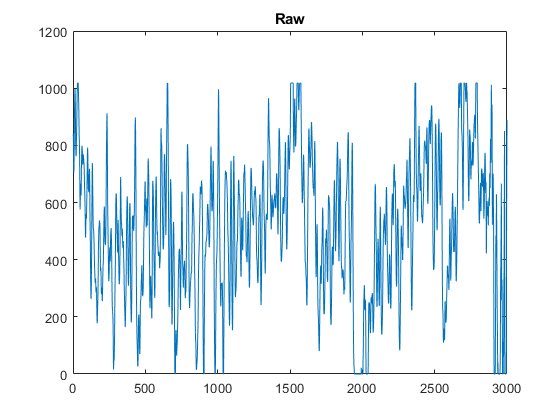



%%%plotting the alph, beta, gamma, theta etc
plot(s), title("Raw")

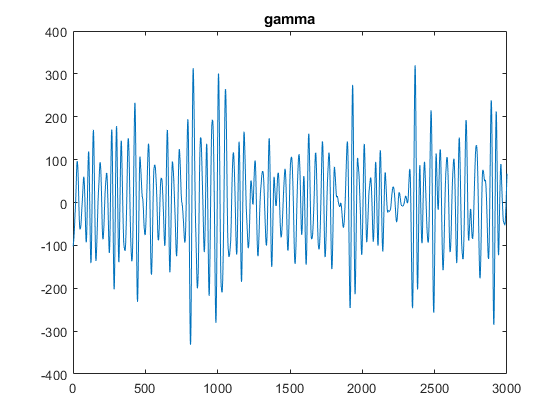


%subplot(3,1,1)
plot(d5), title("gamma")  %%beta

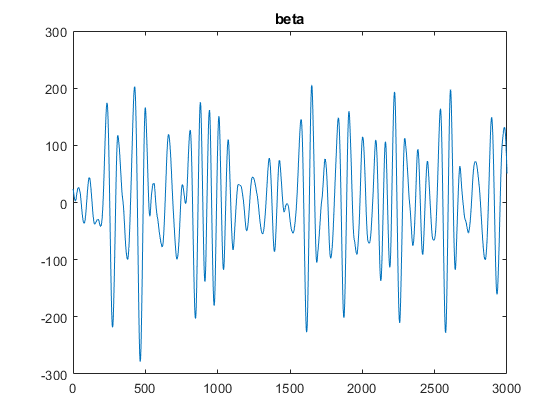


%subplot(3,1,2)
plot(d6), title("beta")   %%beta

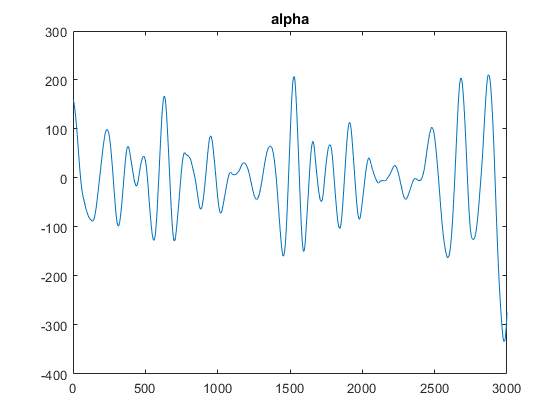


%subplot(3,1,3)
plot(d7), title("alpha")   %%alpha

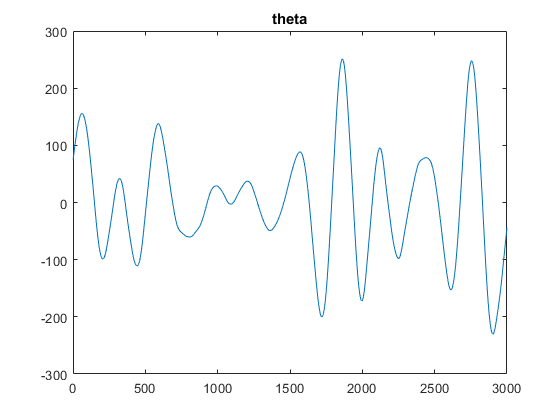


%subplot(3,2,1)
plot(d8), title("theta")   %%theta

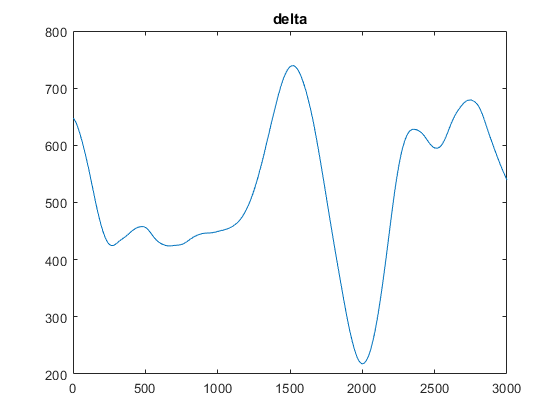


%subplot(3,2,2)
plot(a8), title("delta")   %%theta